% Main figure
hMainFigure = figure( ...
    'Name','Parameter Tuning', ...
    'MenuBar','none', ...
    'Toolbar','none', ...
    'HandleVisibility','callback', ...
    'NumberTitle','off', ...
    'IntegerHandle','off');

A = imread("spectral1.png");
I =imresize(A, 0.5);
hButton = uicontrol('Parent',hMainFigure,...
                    'CData',I,'Position',[3,480,1600/2.72,900/2.72]);

p1 = uipanel('Parent',hMainFigure,'Position',[0 0 0.386 0.58],'BackgroundColor','green','Title','Main Control','FontSize',12);
p2 = uipanel('Parent',hMainFigure,'Position',[0.395 0.598 0.605 0.402],'BackgroundColor','yellow','Title','Autotune','FontSize',12);
p3 = uipanel('Parent',hMainFigure,'Position',[0.395 0 0.3 0.58],'BackgroundColor','cyan','Title','Left Channel','FontSize',12);
p4 = uipanel('Parent',hMainFigure,'Position',[0.7 0 0.3 0.58],'BackgroundColor','magenta','Title','Right Channel','FontSize',12);

autotune = parameterRef;
autotune.name = "autotune";
autotune.value = NaN;
autotune.step = 1; %flag
midi(p2,autotune);

freq_org = 0;
freqValueDisplay = uicontrol('Parent',p2, ...
        'Style','text', ...
        'Position', [115 40 100 30], ...
        'BackgroundColor','white', ...
        'String',freq_org);

midi_org = 0;
midiValueDisplay = uicontrol('Parent',p2, ...
        'Style','text', ...
        'Position', [225 40 100 30], ...
        'BackgroundColor','white', ...
        'String',freq_org);

deviation = parameterRef;
deviation.value = 2000;
deviation.step = 1;
parameterTuning_linear_nolabel(p2,deviation,0,2001,[440,75,270,26],[713,75,40,26],[756,75,50,26],[815,75,60,26],[876,75,48,26])

set_freq = parameterRef;
set_freq.value = 300;
set_freq.step = 1;
parameterTuning_linear_nolabel(p2,set_freq,20,2000,[440,40,270,26],[713,40,40,26],[756,40,50,26],[815,40,60,26],[876,40,48,26])

[pitch_ratio,amplitude_ratio,beat_ratio,vibrato_width,vibrato_rate,freq_lowEnd,...
    freq_highEnd,resolution,f1,f2,f3,f4,f5,a1,a2,a3,a4,a5,t1,t2,t3,t4,t5] = main_panel(p1)

pitch_ratio =   parameterRef - 属性:

     name: "Pitch ratio"
    value: 1
     step: 1.0000e-04


amplitude_ratio =   parameterRef - 属性:

     name: "Ampltd ratio"
    value: 1
     step: 1.0000e-03


beat_ratio =   parameterRef - 属性:

     name: "Beat ratio"
    value: 0
     step: 1.0000e-03


vibrato_width =   parameterRef - 属性:

     name: "Vibrato wid"
    value: 1
     step: 1.0000e-03


vibrato_rate =   parameterRef - 属性:

     name: "Vibrato rate"
    value: 1
     step: 1.0000e-03


freq_lowEnd =   parameterRef - 属性:

     name: "Freq lowEnd"
    value: 0
     step: 1.0000e-03


freq_highEnd =   parameterRef - 属性:

     name: "Freq highEnd"
    value: 0
     step: 1.0000e-03


resolution =   parameterRef - 属性:

     name: "Resolution"
    value: 0
     step: 1.0000e-03


f1 =   parameterRef - 属性:

     name: "f1"
    value: 1
     step: []


f2 =   parameterRef - 属性:

     name: "f2"
    value: 1
     step: []


f3 =   parameterRef - 属性:

     name: "f3"
    value: 1
     step: []


f4 =   parameterRef - 属性:

     name: "f4"
    value: 1
     step: []


f5 =   parameterRef - 属性:

     name: "f5"
    value: 1
     step: []


a1 =   parameterRef - 属性:

     name: "a1"
    value: 1
     step: []


a2 =   parameterRef - 属性:

     name: "a2"
    value: 1
     step: []


a3 =   parameterRef - 属性:

     name: "a3"
    value: 1
     step: []


a4 =   parameterRef - 属性:

     name: "a4"
    value: 1
     step: []


a5 =   parameterRef - 属性:

     name: "a5"
    value: 1
     step: []


t1 =   parameterRef - 属性:

     name: "t1"
    value: 0
     step: []


t2 =   parameterRef - 属性:

     name: "t2"
    value: 0
     step: []


t3 =   parameterRef - 属性:

     name: "t3"
    value: 0
     step: []


t4 =   parameterRef - 属性:

     name: "t4"
    value: 0
     step: []


t5 =   parameterRef - 属性:

     name: "t5"
    value: 0
     step: []



[pitch_ratio_l,amplitude_ratio_l,time_delay_l,vibrato_width_l,vibrato_rate_l,freq_lowEnd_l,...
    freq_highEnd_l,resolution_l,f1_l,f2_l,f3_l,f4_l,f5_l,a1_l,a2_l,a3_l,a4_l,a5_l,...
    t1_l,t2_l,t3_l,t4_l,t5_l] = left_panel(p3)

pitch_ratio_l =   parameterRef - 属性:

     name: "pitch ratio"
    value: 1
     step: 1.0000e-04


amplitude_ratio_l =   parameterRef - 属性:

     name: "ampltd ratio"
    value: 1
     step: 1.0000e-03


time_delay_l =   parameterRef - 属性:

     name: "time delay"
    value: 0
     step: 1.0000e-03


vibrato_width_l =   parameterRef - 属性:

     name: "vibrato wid"
    value: 1
     step: 1.0000e-03


vibrato_rate_l =   parameterRef - 属性:

     name: "vibrato rate"
    value: 1
     step: 1.0000e-03


freq_lowEnd_l =   parameterRef - 属性:

     name: "freq lowEnd"
    value: 0
     step: 1.0000e-03


freq_highEnd_l =   parameterRef - 属性:

     name: "freq highEnd"
    value: 0
     step: 1.0000e-03


resolution_l =   parameterRef - 属性:

     name: "resolution"
    value: 0
     step: 1.0000e-03


f1_l =   parameterRef - 属性:

     name: "f1"
    value: 1
     step: []


f2_l =   parameterRef - 属性:

     name: "f2"
    value: 1
     step: []


f3_l =   parameterRef - 属性:

     name: "f3"
    value: 1
     step: []


f4_l =   parameterRef - 属性:

     name: "f4"
    value: 1
     step: []


f5_l =   parameterRef - 属性:

     name: "f5"
    value: 1
     step: []


a1_l =   parameterRef - 属性:

     name: "a1"
    value: 1
     step: []


a2_l =   parameterRef - 属性:

     name: "a2"
    value: 1
     step: []


a3_l =   parameterRef - 属性:

     name: "a3"
    value: 1
     step: []


a4_l =   parameterRef - 属性:

     name: "a4"
    value: 1
     step: []


a5_l =   parameterRef - 属性:

     name: "a5"
    value: 1
     step: []


t1_l =   parameterRef - 属性:

     name: "t1"
    value: 0
     step: []


t2_l =   parameterRef - 属性:

     name: "t2"
    value: 0
     step: []


t3_l =   parameterRef - 属性:

     name: "t3"
    value: 0
     step: []


t4_l =   parameterRef - 属性:

     name: "t4"
    value: 0
     step: []


t5_l =   parameterRef - 属性:

     name: "t5"
    value: 0
     step: []



[pitch_ratio_r,amplitude_ratio_r,time_delay_r,vibrato_width_r,vibrato_rate_r,freq_lowEnd_r,...
    freq_highEnd_r,resolution_r,f1_r,f2_r,f3_r,f4_r,f5_r,a1_r,a2_r,a3_r,a4_r,a5_r,...
    t1_r,t2_r,t3_r,t4_r,t5_r] = left_panel(p4)

pitch_ratio_r =   parameterRef - 属性:

     name: "pitch ratio"
    value: 1
     step: 1.0000e-04


amplitude_ratio_r =   parameterRef - 属性:

     name: "ampltd ratio"
    value: 1
     step: 1.0000e-03


time_delay_r =   parameterRef - 属性:

     name: "time delay"
    value: 0
     step: 1.0000e-03


vibrato_width_r =   parameterRef - 属性:

     name: "vibrato wid"
    value: 1
     step: 1.0000e-03


vibrato_rate_r =   parameterRef - 属性:

     name: "vibrato rate"
    value: 1
     step: 1.0000e-03


freq_lowEnd_r =   parameterRef - 属性:

     name: "freq lowEnd"
    value: 0
     step: 1.0000e-03


freq_highEnd_r =   parameterRef - 属性:

     name: "freq highEnd"
    value: 0
     step: 1.0000e-03


resolution_r =   parameterRef - 属性:

     name: "resolution"
    value: 0
     step: 1.0000e-03


f1_r =   parameterRef - 属性:

     name: "f1"
    value: 1
     step: []


f2_r =   parameterRef - 属性:

     name: "f2"
    value: 1
     step: []


f3_r =   parameterRef - 属性:

     name: "f3"
    value: 1
     step: []


f4_r =   parameterRef - 属性:

     name: "f4"
    value: 1
     step: []


f5_r =   parameterRef - 属性:

     name: "f5"
    value: 1
     step: []


a1_r =   parameterRef - 属性:

     name: "a1"
    value: 1
     step: []


a2_r =   parameterRef - 属性:

     name: "a2"
    value: 1
     step: []


a3_r =   parameterRef - 属性:

     name: "a3"
    value: 1
     step: []


a4_r =   parameterRef - 属性:

     name: "a4"
    value: 1
     step: []


a5_r =   parameterRef - 属性:

     name: "a5"
    value: 1
     step: []


t1_r =   parameterRef - 属性:

     name: "t1"
    value: 0
     step: []


t2_r =   parameterRef - 属性:

     name: "t2"
    value: 0
     step: []


t3_r =   parameterRef - 属性:

     name: "t3"
    value: 0
     step: []


t4_r =   parameterRef - 属性:

     name: "t4"
    value: 0
     step: []


t5_r =   parameterRef - 属性:

     name: "t5"
    value: 0
     step: []


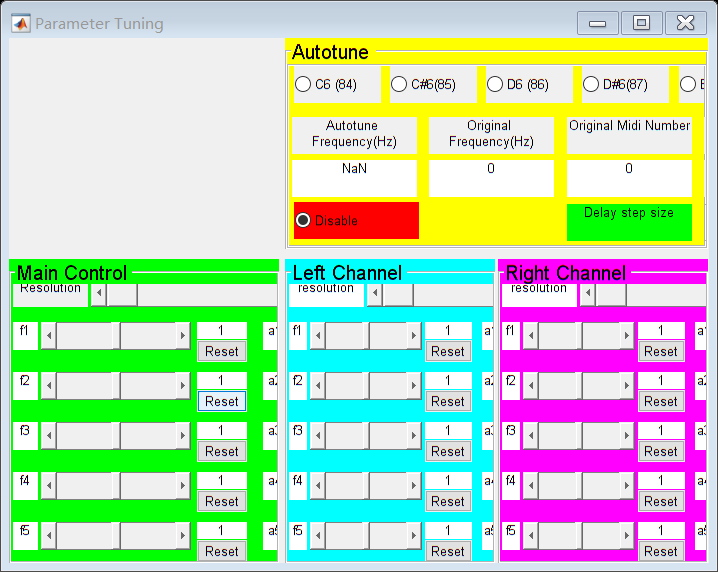


delay_stepsize = parameterRef;
delay_stepsize.value = 0.001;
Edit(p2,delay_stepsize,[335 5 100 30])

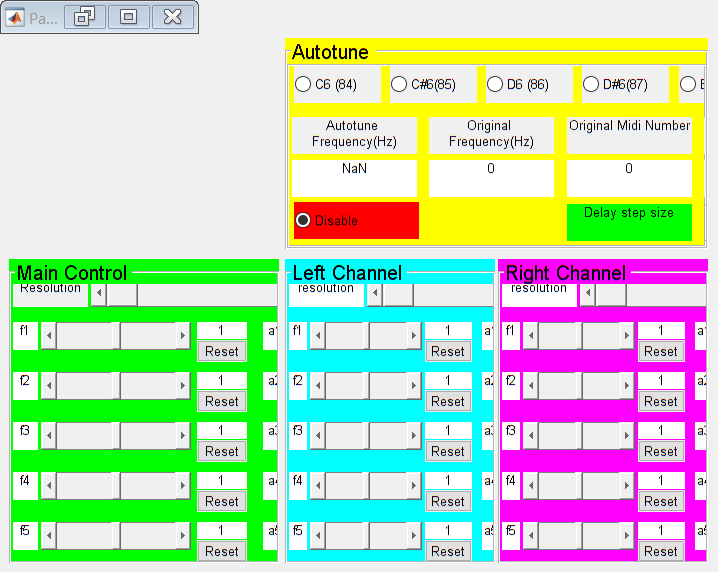

fs = 44100;
frame = 128;
buffer_size = 8;
% frame = 256;
% buffer_size = 4;

% afr = dsp.AudioFileReader('didadi_vocal.wav','ReadRange',[156.5*fs 222*fs],'SamplesPerFrame',frame);
% afr = dsp.AudioFileReader('speech.wav','ReadRange',[1 278*fs],'SamplesPerFrame',frame);
afr = dsp.AudioFileReader('verse1_vocal.wav','SamplesPerFrame',frame);
% afr = dsp.AudioFileReader('Papillon_vocal.wav','SamplesPerFrame',frame); % ,'ReadRange',[10*fs 170*fs]

acc = audioread('verse1_accompaniment.wav');
% acc = audioread('Papillon_accompaniment.wav');


acc = (acc(:,1)+acc(:,2))/2;
acc = acc';

adw = audioDeviceWriter('SampleRate', afr.SampleRate);

c1 = 80; %80
c2 = 350; %300
c3 = 1000;
Phi = 0;
freq = 11000;

buffer = zeros(1,5*fs);
sst = 1;

sample_buffer = zeros(1,buffer_size*frame);
for i = 1:buffer_size
    audio = afr();
    audio = (audio(:,1)+audio(:,2))/2;
    sample_buffer(1+(i-1)*frame:i*frame) = audio';
end

clear_it(p2,afr,[775 5 100 30])

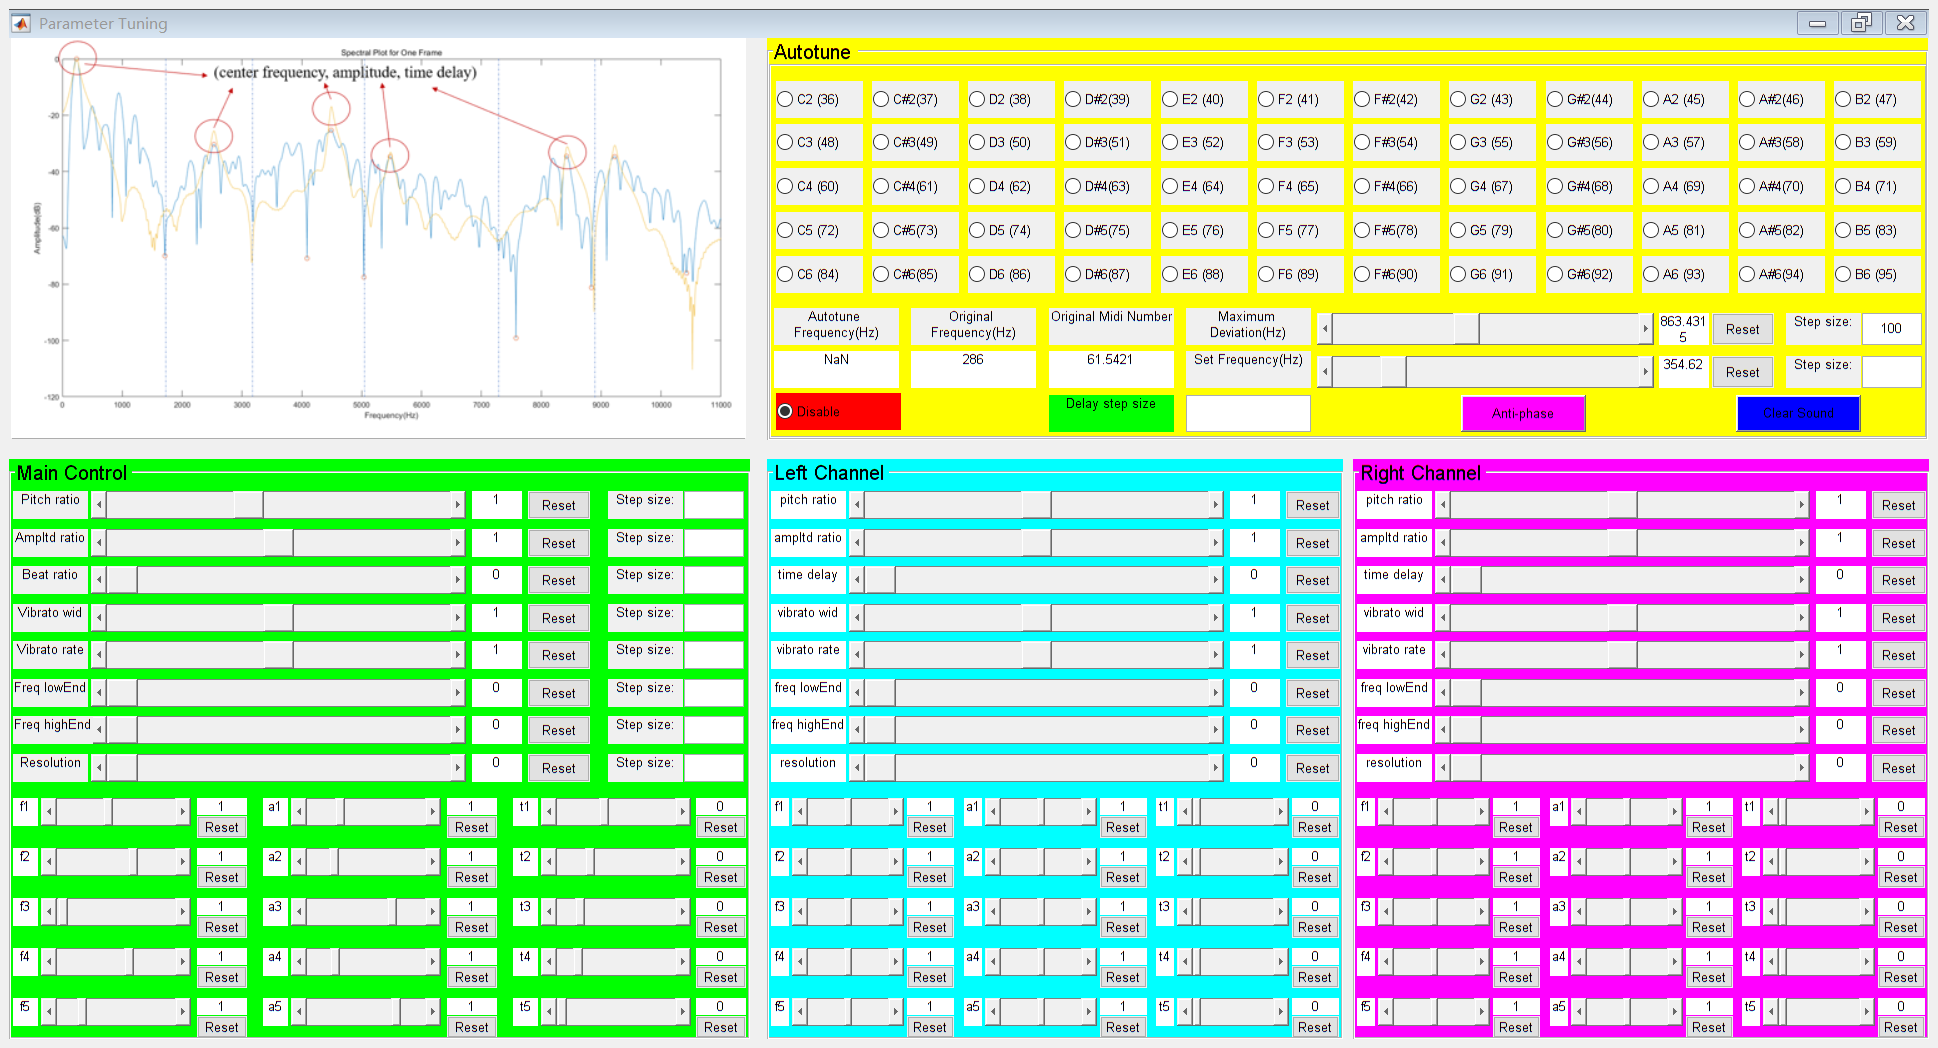

x = 1; % frequency
store = 1;
update = [];
ct = 0;

x_array = [1 1 1 1 1];
store_array = [1 1 1 1 1];
update_array = cell(1,5);

x2 = 1; % amplitude
store2 = 1;
update2 = [];

x2_array = [1 1 1 1 1];
store2_array = [1 1 1 1 1];
update2_array = cell(1,5);

x3_array = [0 0 0 0 0];
store3_array = [0 0 0 0 0];
update3_array = cell(1,5);

x_auto = 300; % autotune frequency
store_auto = 300;
update_auto = [];

x_dev = 2000;
store_dev = 2000;
update_dev = [];

acc_count = 0;
while ~isDone(afr)
    
     audio = afr(); %[1024,2]
    audio = (audio(:,1)+audio(:,2))/2;
%     audio = audio(:,1);

    sample_buffer(1:(buffer_size-1)*frame) = sample_buffer(1+frame:end);
    sample_buffer((buffer_size-1)*frame+1:end) = audio';
    sample = sample_buffer;
    
    S = 20*log10(abs(fft(sample,fs))+0.00001);
    S_0db = S - max(S(1:freq));
    S_linear = abs(fft(sample,fs));

    order = 350;
    num = round(freq/order);
    points = zeros(1,2*num);
    for i = 1:num
        piece = S_0db((i-1)*order+1:i*order);
        points(i) = find(piece == max(piece),1) + (i-1)*order;
        points(i+num) = find(piece == min(piece),1) + (i-1)*order;
    end
    points = unique(points);
    y_p = S_0db(points);

    o = 5;
    ma = [];
    st = 1;
    for i = 1:500
        cal = abs(y_p(st) - y_p);
        for j = st+1:num*2
            ind = find(cal(st:j) == max(cal(st:j)),1)+st-1;
            if ind + o <= num*2 && ind ~= j && ind == find(cal(st:ind+o) == max(cal(st:ind+o)),1)+st-1
                ma = [ma ind];
                st = ind;
                break
            elseif ind + o > num*2
                ma = [ma ind];
                break
            end
        end
        if ind + o > num*2 || j == num*2
            break
        end
    end

    order = 550;
    num = round(freq/order);
    points2 = zeros(1,num);
    for i = 1: num
        piece = S_0db((i-1)*order+1:i*order);
        points2(i) = find(piece == max(piece),1) + (i-1)*order;
    end
    points2 = [1 points2];
    y_p = S_0db(points2);

    pt = unique([points2 points(ma)]);
    M =  [1 points(ma)];
    yM = S_0db(M);
    Parameter = [];
    Parameter2 = [];
    
    if length(M) > 3
        Parameter = zeros(4,ceil((length(M)-2)/2)); % center frequency; amplitude; bandwidth; skirt width
        Parameter2 = zeros(4,ceil((length(M)-2)/2));
        c = 0;
        
        freq_ratio_array = [f1.value,f2.value,f3.value,f4.value,f5.value];
        amp_ratio_array = [a1.value,a2.value,a3.value,a4.value,a5.value];
        time_delay_array = [t1.value,t2.value,t3.value,t4.value,t5.value];
        
        for i = 2:length(M)-1
            if yM(i) > yM(i-1) && yM(i) > yM(i+1)
                c = c + 1;
                
                if c == 1 
                    if ~isnan(autotune.value)
                        if store_auto ~= set_freq.value
                            autotune.step = 0;
                        end
                        
                        if autotune.step == 0 % set frequency
                            [freqq,x_auto,store_auto,update_auto] = line_step(x_auto,store_auto,set_freq.value,set_freq.step,1,1,update_auto);
                        elseif autotune.step == 1 % midi
                            freqq = autotune.value;
                            x_auto = autotune.value;
                            store_auto = set_freq.value;
                        end
                            
                        if M(i) > 800
                            r = 1;
                        else
                            [dev,x_dev,store_dev,update_dev] = line_step(x_dev,store_dev,deviation.value,deviation.step,1,1,update_dev);
                            if freqq > M(i)
                                r = min(freqq,M(i) + dev)/M(i);
                            else
                                r = max(freqq,M(i) - dev)/M(i);
                            end
                        end  
                        
                    else
                        r = 1;
                            
                    end
                    
                    
                    ct = ct + 1;
                    if mod(ct,50) == 0 && M(i) < 800
                        freq_org = M(i);
                        midi_org = log2(freq_org/440)*12+69;
                        set(freqValueDisplay,'String',num2str(freq_org));
                        set(midiValueDisplay,'String',num2str(midi_org));
                    end
                end
                
                [parameter,x,store,update] = line_step(x,store,pitch_ratio.value,pitch_ratio.step,r,M(i),update);
                if c <= 5
                    [parameter,x_array(c),store_array(c),update_array{c}] = line_step(x_array(c),store_array(c),freq_ratio_array(c),pitch_ratio.step,1,parameter,update_array{c});
                end
                Parameter(1,c) = parameter;

                amp = norm(S_linear(M(i-1):M(i+1)))/sqrt(M(i+1)-M(i-1)+1);
                [parameter,x2,store2,update2] = line_step(x2,store2,amplitude_ratio.value,amplitude_ratio.step,1,amp,update2);
                if c <= 5
                    [parameter,x2_array(c),store2_array(c),update2_array{c}] = line_step(x2_array(c),store2_array(c),amp_ratio_array(c),amplitude_ratio.step,1,parameter,update2_array{c});
                end
                Parameter(2,c) = parameter;
                

                st = find(pt == M(i-1));
                ed = find(pt == M(i+1));
                pt_band = pt(st:ed);
                maxima = find(pt_band == M(i));
                peak = S_0db(pt_band(maxima));
                y_band = S_0db(pt_band);
                fr = find(y_band(1:maxima) < peak - 6,1,'last');
                nt = find(y_band(maxima:end) < peak - 6,1)+maxima-1;
                if isempty(fr)
                    fr = 1;
                end
                if isempty(nt)
                    nt = length(y_band);
                end
                bw_i = [fr maxima nt];
                bw_sample = pt_band(bw_i);
                bw = y_band(bw_i);

                Parameter(3,c) = (6*(bw_sample(2) - bw_sample(1))/(bw(2) - bw(1)) + 6*(bw_sample(3) - bw_sample(2))/(bw(2) - bw(3)))/2;
                Parameter(4,c) = max(M(i+1) - M(i),M(i) - M(i-1))*2; 
            end
        end
        [~,col] = size(Parameter);

        index = [];
        for i = 1:col
            if isequal(Parameter(:,i), zeros(4,1))
                index = [index i];
            end
        end
        Parameter(:,index) = [];
        [~,col] = size(Parameter);

        if col > 0
            f0 = Parameter(1,1);
            step = round(fs/f0);
            for i = 1:col
                beta = Parameter(4,i);
                t = pi/beta;
                alpha = min(Parameter(3,i),c1)*pi;

                f = Parameter(1,i); % *ratio(i);
                omega = 2*pi*f;
                kn1 = [0:fs*t-1]/fs;
%                 vibrato_width = 0.01*f;
%                 vibrato_rate = randi(10);
                vibrato_width = 0;
                vibrato_rate = 0;
                s1 = (1 - cos(beta*kn1))/2.*exp(-alpha*kn1).*sin(omega*kn1+vibrato_width*cos(2*pi*vibrato_rate*kn1)+Phi);
                for ts = 1:3000
                    st = exp(-alpha*t*ts);
                    if st < 0.003
                        break
                    end
                end
                kn2 = [t*fs:t*fs*ts]/fs;
                s2 = exp(-alpha*kn2).*sin(omega*kn2 + vibrato_width*cos(2*pi*vibrato_rate*kn2)+Phi);
                s = [s1 s2];

                if Parameter(3,i) > c2 && Parameter(3,i) <= c3
                    s = conv(s,rand(1,length(s)+1)*2-1);
                elseif Parameter(3,i) > c3
                    s = conv(s,rand(1,length(s)+1)*2-1);
                    s = conv(s,rand(1,length(s)+1)*2-1);
                end

                s = s/max(abs(s))*Parameter(2,i);
                
                % add dispersion
                dls = 0;
                if i <= 5
                    [dls,x3_array(i),store3_array(i),update3_array{i}] = line_step(x3_array(i),store3_array(i),time_delay_array(i),delay_stepsize.value,1,1,update3_array{i});
                end
                dl = round(fs*dls);
                start = sst + dl;
                buffer(start:start+length(s)-1) = buffer(start:start+length(s)-1)+s;
                
                
                while step < frame/2
                    step = 2*step;
                end
                sstt = sst + step;
                while sstt < frame
                    buffer(sstt+ dl:sstt+ dl+length(s)-1) = buffer(sstt+ dl:sstt+ dl+length(s)-1)+s;
                    sstt = sstt + step;
                end
                
            end
            
            sst = sst + step;
            while sst < frame
                sst = sst + step;
            end
        else
            sst = sst + frame;
        end
    else
        sst = sst + frame;
    end

    sst = sst - frame;
    while sst >= frame
        audio = afr();
        sst = sst - frame;
        
        output = buffer(1:frame);
        output = output/120;

        adw(output');

        buffer(1:end-frame) = buffer(frame+1:end);
        buffer(end-frame+1:end) = zeros(1,frame);
    end
    if sst == 0
        sst = 1;
    end
    
    drawnow limitrate
    
    output = buffer(1:frame);
    output = output/120;
    
    output =  output + acc(1 + acc_count*frame:frame + acc_count*frame)/2*beat_ratio.value;
    acc_count = acc_count + 1;

    adw(output');

    buffer(1:end-frame) = buffer(frame+1:end);
    buffer(end-frame+1:end) = zeros(1,frame);
    
end


for i = 1:round(3*fs/frame)
    output = buffer(1:frame);
    output = output/120;

    adw(output');

    buffer(1:end-frame) = buffer(frame+1:end);
    buffer(end-frame+1:end) = zeros(1,frame);
end

release(afr); 
release(adw);